# Spatial Filtering of Color Images

    Pemrosesan spasial pada gambar berwarna dengan pemfilteran linier (linear filtering) dibagi menjadi 2 teknik, yaitu penghalusan gambar (smoothing) dan penajaman gambar (sharpening).

## Membaca Gambar

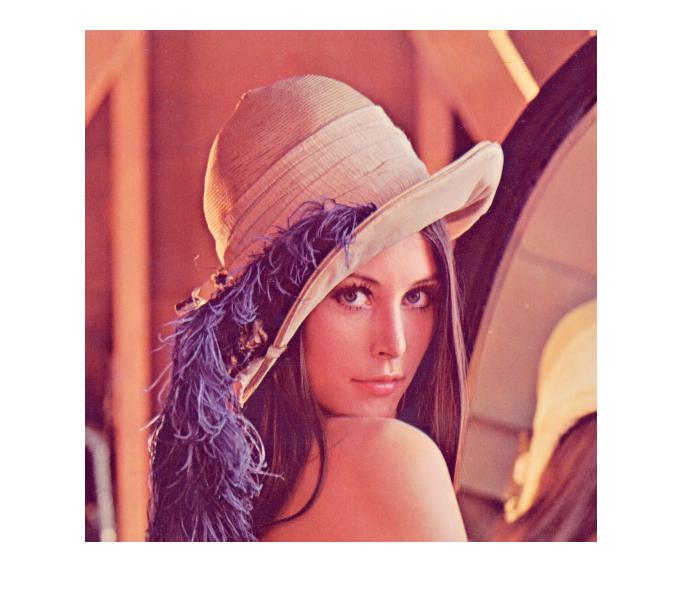

I = imread('./Input/Lena.tif');
imshow(I);

## Color Image Smoothing

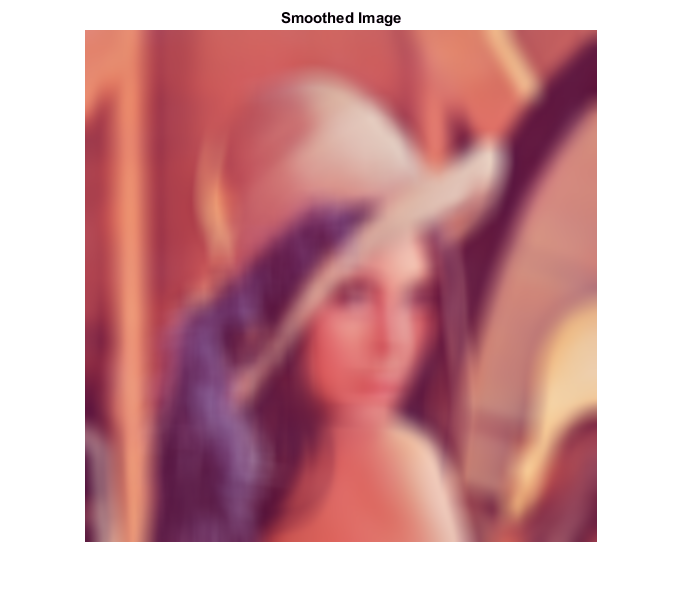

fRed = I(:, :, 1);
fGreen = I(:, :, 2);
fBlue = I(:, :, 3);
filter = fspecial('average', 25);

filterRed = imfilter(fRed, filter, 'replicate');
filterGreen = imfilter(fGreen, filter, 'replicate');
filterBlue = imfilter(fBlue, filter, 'replicate');

I_smooth = cat(3, filterRed, filterGreen, filterBlue);
% I_smooth = imfilter(I, filter, 'replicate');    %cara lain

imwrite(I_smooth, '.\Output\Lena_smooth.tif');
imshow(I_smooth);
title('Smoothed Image');

## Color Image Sharpening

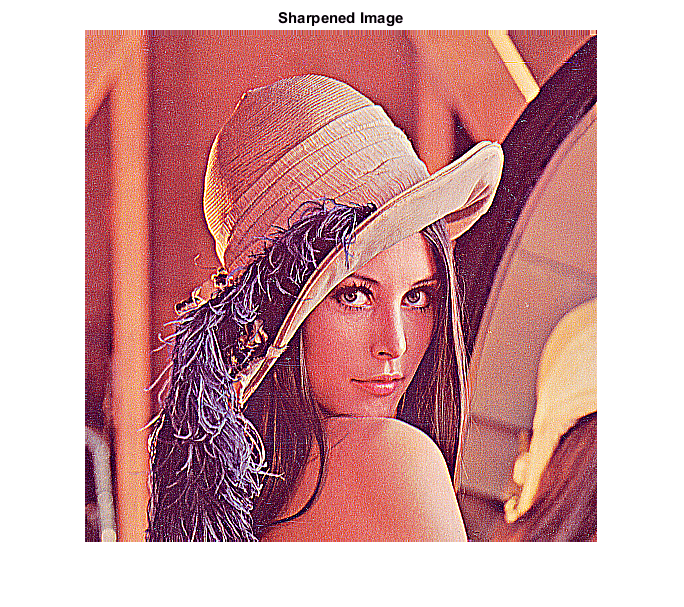

laplacianMask = [1 1 1; 1 -8 1; 1 1 1];

I2 = im2double(I);

I_sharp = I2 - imfilter(I2, laplacianMask, 'replicate');

imwrite(I_sharp, '.\Output\Lena_sharp.tif');
imshow(I_sharp);
title('Sharpened Image');

## Perbandingan

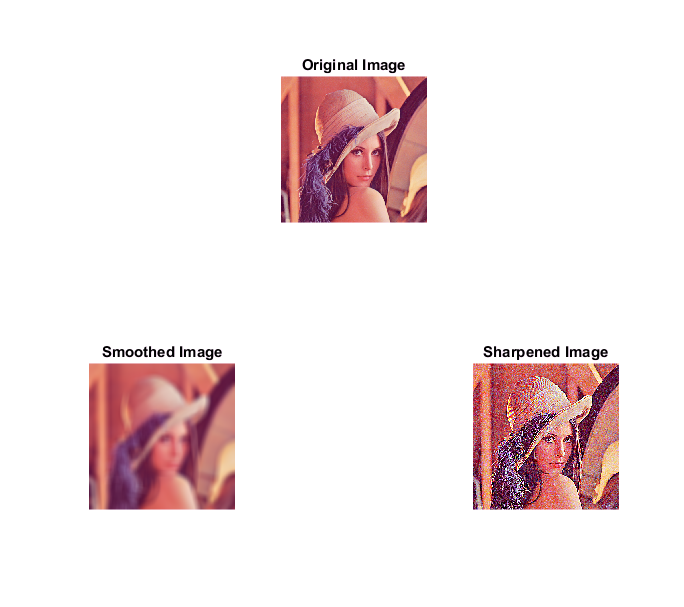

subplot(2,3,2); imshow(I);
title('Original Image');
subplot(2,3,4); imshow(I_smooth);
title('Smoothed Image');
subplot(2,3,6); imshow(I_sharp);
title('Sharpened Image');